# Recursive Least Squares estimation

## Introduction

### Purpose

The purpose of this notebook is to show the effectiveness of a recursive algorithm for the estimation of the admittance matrix.

Moreover, we aim at assessing the increase in accuracy and convergence speed achieved by properly parametrizing the admittance matrix, in order to remove redundant parameters.

### Method

We define a simple DC microgrid, with $n=4$ nodes, $n_l=2$ loads and $n_g=2
$ generators. Loads are modelled as ZIP, with a constant power, a constant current and a constant impedence component. For a generic load l, it holds $V_l = \bar I + \bar Y I_l + \frac{\bar P}{I_l}$. We also define the admittance matrix $Y$ of the grid. By construction, such $Y$ is Laplacian, that is symmetric, positive semidefinite and with zero row sum. A series of samples of generator voltages $V_g$ is than simulated, with each voltage modelled as a Gaussian random variable. From generator voltages, load voltages $V_l$ are derived using power flow equations. When more solutions are feasible, we always choose the high-voltage one. Finally, currents $I$ are derived by the relation $I = YV$, where $V = [V_g V_L]^T$.

Using samples of $I$ and $V$ as input, a rescursive least square algorithm is run in order to estimate $Y$. Three different flavours of the RLS are tested, differing in the number of free parameters:

- A naive verson (RLS1) assumes that the whole matrix $Y$ has to be estimated, resulting in $n^2$ free parameters. This approach is implemented by keeping $Y$ as a matrix.

- A vectorized version (RLS2) exploits the relies on the half-vectorization of $Y$, $vech(Y)$. By imposing a symmetric structure, the number of free parameters is reduced to $n(n+1)/2$ and, by exploiting vectorization, we can rely on the standard RLS formulae. However, the constraint on the row sum is not yet enforced. This is similar to the approach by Claire Tomlin [**1**]

- An enhanced vectorized version (RLS3) adopts a new form of vectorization which enforces both the symmetric structure and the zero row sum, thus further reducing the number of free parameters to $n(n-1)/2$. This approach is enabled by a novel algorithm to create a matrix $Q$ such that $vech(Y) = Q * v(Y)$, where $v(Y)$ is a vector containing only the free parameters of Y. Then, the well-known duplication matrix $D$ can be used to recover the full vectorization of $Y$ and thus whole matrix [**2**]. $vec(Y) = D * vech(Y) = D*Q*v(Y)$.

The speed of convergence and the accuracy of the estimates are evaluated, both visually and quantitavely. Let $\hat Y$ denote the estimated admittance matrix. The Frobenius norm and the max norm of the error matrix $E = |Y - \hat Y|
$ are used to assess the goodness of fit.

### Conclusion

TODO

### Next Steps

- Improve and make more elegant the algorithm to build Q

- Find - if possible - a matrix costruction for Q - like in the paper about D [**2**]

- Check if our RLS formula is consistent with [**3**]

- Test on an improved simulator (be careful about Sahel's suggestions!)

### Refrences

- Ardakanian - On Identification of Distribution Grids

- Jan R Magnus - The elimination matrix: Some lemmas and applications

- Luis A Escobar - A Note on the Updating of Regression Estimates

## Development

### Grid definition

Parameters for the grid are:

- the Laplacian admittance matrix $Y
$

- the load paramenters $\bar I
$, $\bar P$ and $\bar Y$

clear all
close all
rng default

I_bar = [15, 5]';
Y_bar = [0.01, 0.05]';
P_bar = [1200, 800]';
Y = [3 0 -2 -1; 0 2 -1 -1; -2 -1 3 0; -1 -1 0 2];
n = length(Y); % nodes
nl = length(Y_bar); % loads
ng = n - nl; % generators

### Sample collection

We simulate generator voltages as incorrelated random variables, oscillating around a mean value, and we compute load voltages using power flow equations. Then, we build voltages using the equation $I = YV + e$, where $e$ is gaussian noise, with arbitrary variance. We take a variable number of samples for currents and voltages, 100 by default.

samples = 100;
Vg = normrnd(200, 5, ng, samples);
Vl = zeros(nl, samples);
for i = 1:samples
    Vl_var = sym('Vl_var', [nl, 1]);
    Vl_symb = vpasolve(fl(Vg(:, i), Vl_var, I_bar, Y_bar, P_bar, Y) == 0, Vl_var);
    [~, i_max] = max(Vl_symb.Vl_var1 + Vl_symb.Vl_var2);
    Vl(:, i) = [Vl_symb.Vl_var1(i_max), Vl_symb.Vl_var2(i_max)]';
end
V = [Vg; Vl];
% V = normrnd(200, 10, n, samples);
I_clean = Y * V;
e = normrnd(0, 0, n, samples); % no noise at the moment
I = I_clean + e;

#### Balance check

We check that the power flow equations are always satisfied, in order to certify the goodness of the data

I_check = zeros(nl, samples);
P_check = zeros(nl, samples);
for i = 1:samples
    P_check = fg(Vg(:, i), Vl(:, i), Vg(:, i).*I_clean(1:ng, i), Y);
    I_check = fl(Vg(:, i), Vl(:, i), I_bar, Y_bar, P_bar, Y);
end
max(abs(P_check))

ans = 7.7307e-12

max(abs(I_check))

ans = 5.4179e-14

We also check the correlation between voltages

corr(V')

ans =     1.0000   -0.0243    0.8918    0.6975
   -0.0243    1.0000    0.4306    0.6994
    0.8918    0.4306    1.0000    0.9462
    0.6975    0.6994    0.9462    1.0000


### Naive Recursive Least Square (RLS1)

We implement a recursive least square (RLS) estimator for $Y$, with a forgetting factor $\lambda$. However, we do not take into account the structure of the admittance matrix. Thus, the Laplacian is not assured to be symmetric nor to have a zero-row sum and the number of paramters to estimate is $n^2$, where $n$ is the number of nodes (generator and loads) in the network. Arbitrary initial guesses for both the admittance matrix and the variance of its parameters must be provided. 

lambda = 0.9;
Y1_hat = [];
Y1_hat(:, :, 1) = 0.1 * ones(n);
Z1 = [];
Z1(:, :, 1) = 100 * eye(n);
for i = 2:samples
    Z1(:, :, i) = (1/lambda) * (Z1(:, :, i-1) - Z1(:, :, i-1) * V(:, i) * inv(lambda + V(:, i)' * Z1(:, :, i-1) * V(:, i)) * V(:, i)' * Z1(:, :, i-1));
    Y1_hat(:, :, i) = Y1_hat(:, :, i-1) + (I(:, i) - Y1_hat(:, :, i-1) * V(:, i)) * V(:, i)' * Z1(:, :, i);
end

We first check the final results

Y1_hat(:, :, end)

ans =     3.0009    0.0203   -1.9425   -1.0802
   -0.0019    1.9594   -1.1151   -0.8394
   -2.0045   -1.0962    2.7272    0.3808
   -0.9945   -0.8839    0.3293    1.5403


Z1(:, :, end)

ans = 	1.0e+05 *

    0.0010    0.0213    0.0604   -0.0843
    0.0213    0.4505    1.2778   -1.7837
    0.0603    1.2778    3.6245   -5.0596
   -0.0843   -1.7837   -5.0596    7.0629


### Recursive Least Square with half-vectorization (RLS2)

Next, we implement a RLS where the parameters are the half-vectorization of the matrix Y. This drops the number of free parameters to $n(n+1)/2$ but does not ensure the zero-row-sum property.

rls2_free_params = n*(n+1)/2;
y_hat = [];
y_hat(:, 1) = 0.1 * ones([rls2_free_params, 1]);
Z2 = [];
Z2(:, :, 1) = 100 * eye(rls2_free_params);
D = duplication_matrix(n);
Y2_hat = [];
Y2_hat(:, :, 1) = reshape(D * y_hat(:, 1), [n n]);
for i = 2:samples
    a = kron(V(:, i), eye(n))' * D;
    Z2(:, :, i) = (1/lambda) * (Z2(:, :, i-1) - Z2(:, :, i-1) * a' * inv(lambda * eye(n) + a * Z2(:, :, i-1) * a') * a * Z2(:, :, i-1));
    y_hat(:, i) = y_hat(:, i-1) + Z2(:, :, i) * a' * (I(:, i) - a * y_hat(:, i-1));
    Y2_hat(:, :, i) = reshape(D * y_hat(:, i), [n n]);
end

We check the results

Y2_hat(:, :, end)

ans =     2.9999   -0.0016   -2.0044   -0.9938
   -0.0016    1.9670   -1.0937   -0.8692
   -2.0044   -1.0937    2.7341    0.3712
   -0.9938   -0.8692    0.3712    1.4819


Z2(:, :, end)

ans = 	1.0e+05 *

    0.0000    0.0000   -0.0000   -0.0000    0.0001    0.0001   -0.0002    0.0004   -0.0005    0.0007
    0.0000    0.0000    0.0001   -0.0002    0.0009    0.0026   -0.0037    0.0075   -0.0105    0.0146
   -0.0000    0.0001    0.0004   -0.0005    0.0026    0.0075   -0.0104    0.0212   -0.0296    0.0413
   -0.0000   -0.0002   -0.0005    0.0007   -0.0037   -0.0104    0.0146   -0.0296    0.0413   -0.0577
    0.0000    0.0009    0.0026   -0.0037    0.0197    0.0558   -0.0780    0.1584   -0.2211    0.3087
    0.0001    0.0026    0.0075   -0.0104    0.0558    0.1584   -0.2211    0.4494   -0.6273    0.8756
   -0.0002   -0.0037   -0.0104    0.0146   -0.0780   -0.2211    0.3087   -0.6273    0.8757   -1.2224
    0.0004    0.0075    0.0212   -0.0296    0.1584    0.4494   -0.6273    1.2748   -1.7795    2.4840
   -0.0005   -0.0104   -0.0296    0.0413   -0.2211   -0.6273    0.8756   -1.7795    2.4840   -3.4674
    0.0007    0.0146    0.0413   -0.0577    0.3087    0.8757   -1.2224   

## Recursive Least Square without redundant parameters (RLS3)

Finally, we implement a similar RLS algorithm which takes into account the constraints on the Laplacian admittance matrix and thus reduces the number of free parameters from to $n(n-1)/2$.

rls3_free_params = n*(n-1)/2;
x_hat = [];
x_hat(:, 1) = 0.1 * ones([rls3_free_params, 1]);
Z3 = [];
Z3(:, :, 1) = 100 * eye(rls3_free_params);
Q = D * transformation_matrix(n);
Y3_hat = [];
Y3_hat(:, :, 1) = reshape(Q * x_hat(:, 1), [n n]);
for i = 2:samples
    a = kron(V(:, i), eye(n))' * Q;
    Z3(:, :, i) = (1/lambda) * (Z3(:, :, i-1) - Z3(:, :, i-1) * a' * inv(lambda * eye(n) + a * Z3(:, :, i-1) * a') * a * Z3(:, :, i-1));
    x_hat(:, i) = x_hat(:, i-1) + Z3(:, :, i) * a' * (I(:, i) - a * x_hat(:, i-1));
    Y3_hat(:, :, i) = reshape(Q * x_hat(:, i), [n n]);
end

We check the results:

Y3_hat(:, :, end)

ans =     3.0000    0.0000   -2.0000   -1.0000
    0.0000    2.0000   -1.0000   -1.0000
   -2.0000   -1.0000    3.0000    0.0000
   -1.0000   -1.0000    0.0000    2.0000


Z3(:, :, end)

ans =     0.0099    0.1015   -0.0834   -0.0323    0.0262    0.3232
    0.1015    1.2504   -1.0291   -0.3942    0.3245    3.9859
   -0.0834   -1.0291    0.8478    0.3244   -0.2673   -3.2821
   -0.0323   -0.3942    0.3244    0.1252   -0.1028   -1.2539
    0.0262    0.3245   -0.2673   -0.1028    0.0851    1.0323
    0.3232    3.9859   -3.2821   -1.2539    1.0323   12.7381


## Goodness of fit

### Matrix elements

We check the evolution of the estimated admittance matrix Y with each algorithm

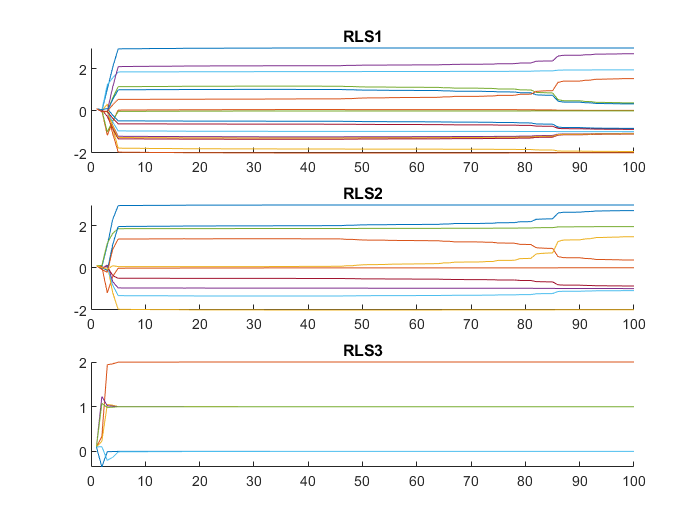

subplot(3, 1, 1);
hold on
for i=1:n
    for j=1:n
        plot(1:samples, squeeze(Y1_hat(i, j, :)));
    end
end
title('RLS1');
hold off
subplot(3, 1, 2);
hold on
for i=1:rls2_free_params
    plot(1:samples, squeeze(y_hat(i, :)));
end
title('RLS2');
hold off
subplot(3, 1, 3);
hold on
for i=1:rls3_free_params
    plot(1:samples, squeeze(x_hat(i, :)));
end
title('RLS3');
hold off

### Error metrics

Finally, we resort to some error metrics to evaluate the goodness of fit. Error metrics are the Frobenius norm and the max norm of the matrix $Y_e = \left |Y - \hat Y \right|$.

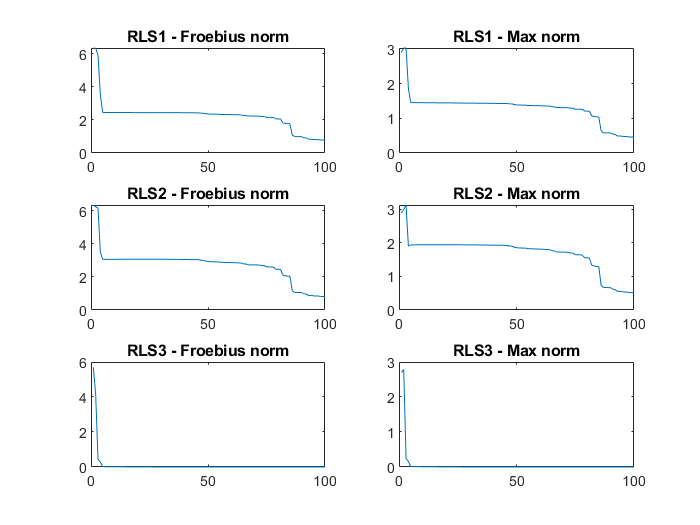

Ys_hat = {Y1_hat, Y2_hat, Y3_hat};
for i=1:3
    Y_hat = cell2mat(Ys_hat(i));
    Ye = abs(Y_hat - Y);
    froeb_norm = [];
    max_norm = [];
    for j = 1:samples
        froeb_norm(j) = norm(Ye(:, :, j), 'fro');
        max_norm(j) = max(max(Ye(:, :, j)));
    end
    subplot(3, 2, 2*i - 1);
    plot(1:samples, squeeze(froeb_norm));
    title(['RLS' num2str(i) ' - Froebius norm']);
    subplot(3, 2, 2*i);
    plot(1:samples, squeeze(max_norm));
    title(['RLS' num2str(i) ' - Max norm']);
end